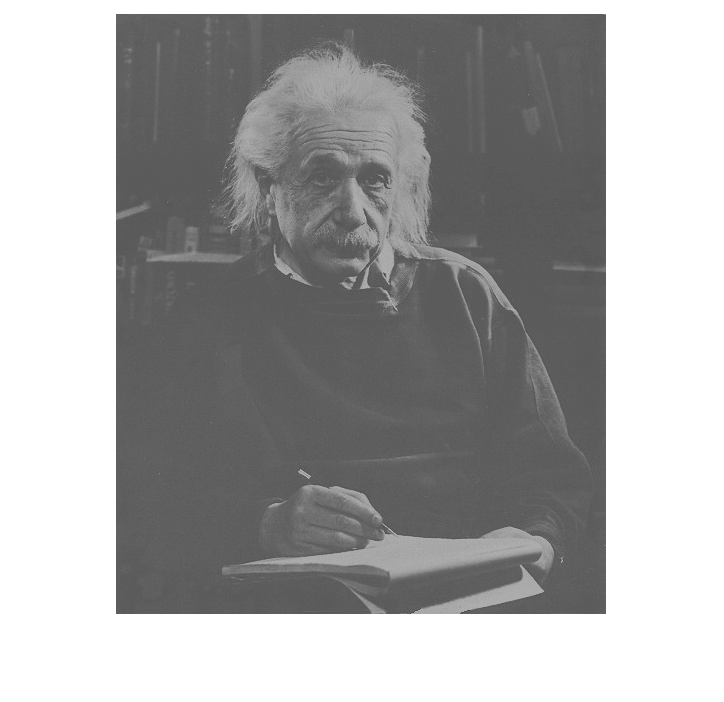

clear;clf;
img = imread("../images/einstein_low_contrast.tif");
[M, N] = size(img);
imshow(img)

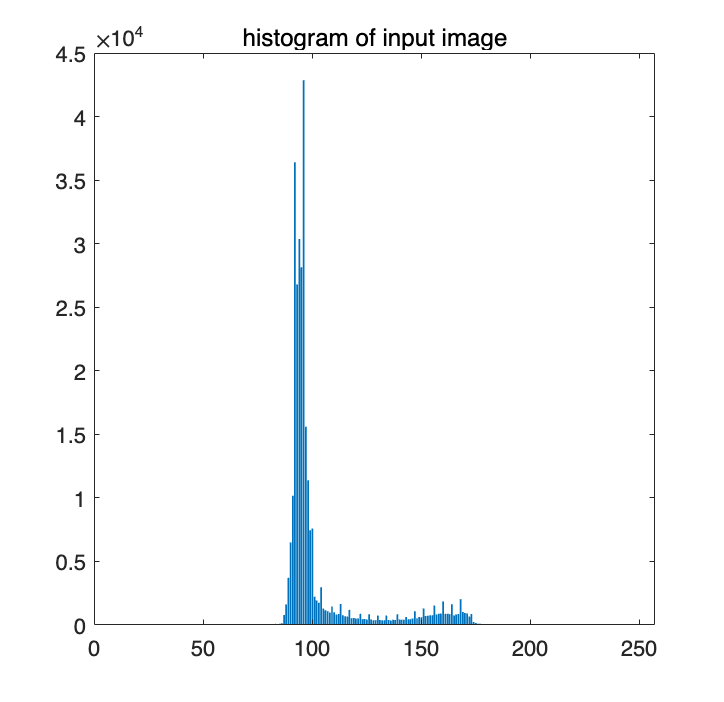

hist_img = zeros(256, 1);
for i = 0:255
%   count histogram
    hist_img(i+1) = sum(sum(img == i));
end
bar(hist_img);title('histogram of input image')

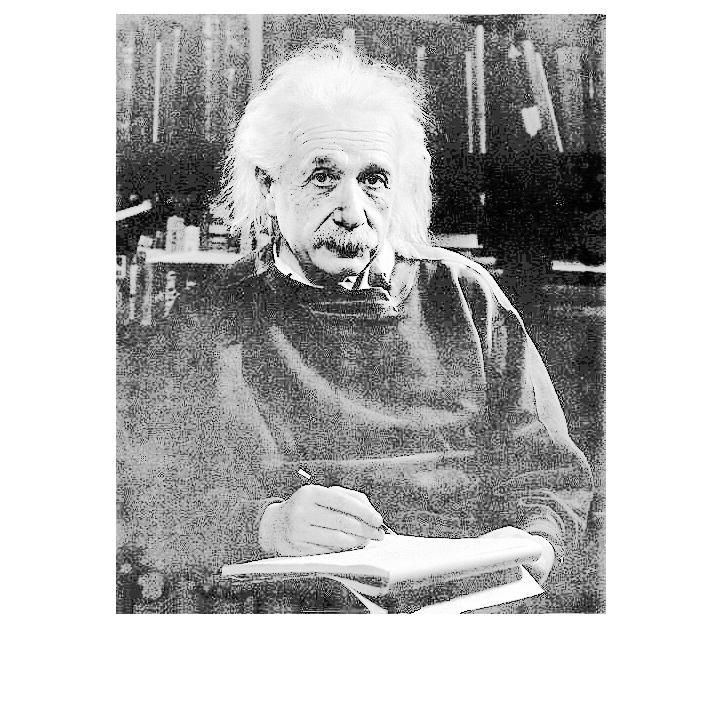

% get distribution
distribution_img = hist_img / (M * N);
result = zeros(size(img));
prefix_sum = 0;
for i = 1:256
    prefix_sum = prefix_sum + distribution_img(i);
%     get mapped intensity
    map_idx = round(255 * prefix_sum);
    result(img == i-1) = map_idx;
end
imshow(uint8(result))

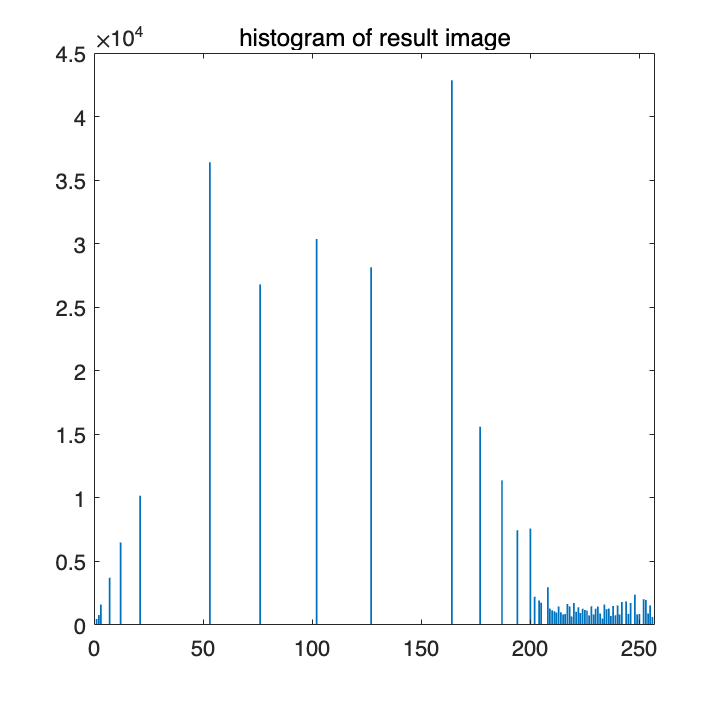

hist_res_img = zeros(256, 1);
for i = 0:255
    hist_res_img(i+1) = sum(sum(result == i));
end
bar(hist_res_img);title('histogram of result image')